collection1 = dicomCollection("Sijainti");


%coordinates
x = ;
y = ;
z = ;


p = 3;%Josta vaihekuvat alkaa
o = p-1;
for i=p:height(collection1)
    medVol = medicalVolume(collection1.("Filenames")(i));
    %Seuraavassa valitaan leike: (medVol, leikkeen numero, "transverse")
    [X,position,spacings] = extractSlice(medVol,z,"transverse");
    %Seuraavassa valitaan vokseli: X(Kuvan y-koordinaatti, x-koordinaatti)
    data1(i-o) = X(y,x); 
end

data1 = double(data1) %poistaa int16

data1 =    555   543   534   523   526   512   499   492   482   465   452   436   425   393   375   348   323   278   245   200   147    99    46    22    21    38    83   116   147   176   199   226   239   264   280   300   311   326   340   354   367   376   392   404   419   433   457   472   486   503





%B0-korjaus:
b0_map_stack_1 = medicalVolume(collection1.("Filenames")(2));
[b0_map_image_1,position,spacings] = extractSlice(b0_map_stack_1,z,"transverse");
b0_1 = b0_map_image_1(y,x);
b0_1 = double(b0_1); %poistaa int16
b0_1 = b0_1 - 2048

b0_1 = -31

%data1 = data1 + b0_1

%NORMITUS
medVol_ref1 = medicalVolume(collection1.("Filenames")(1));
[X,position,spacings] = extractSlice(medVol_ref1,z,"transverse");
data_ref1 = X(y,x);
data_ref1 = double(data_ref1); %poistaa int16
data_ref1 = data_ref1 + b0_1;
data1 = data1 ./ data_ref1

data1 =     0.7510    0.7348    0.7226    0.7077    0.7118    0.6928    0.6752    0.6658    0.6522    0.6292    0.6116    0.5900    0.5751    0.5318    0.5074    0.4709    0.4371    0.3762    0.3315    0.2706    0.1989    0.1340    0.0622    0.0298    0.0284    0.0514    0.1123    0.1570    0.1989    0.2382    0.2693    0.3058    0.3234    0.3572    0.3789    0.4060    0.4208    0.4411    0.4601    0.4790    0.4966    0.5088    0.5304    0.5467    0.5670    0.5859    0.6184    0.6387    0.6576    0.6806



%Määritetään x-akseli (yksikkö ppm, sekä oikeat ppm-arvot iniFilestä)
start_value1 = -5;
end_value1 = 5;
increment = 0.2;
ppm_x1 = linspace(start_value1, end_value1, (end_value1 - start_value1) / increment + 1);

ppm_Hz = 127.732434

ppm_Hz = 127.7324

b0_ppm_1 = b0_1 / ppm_Hz

b0_ppm_1 = -0.2427


%B0-korjaus:
ppm_x1 = ppm_x1 - b0_ppm_1

ppm_x1 =    -4.7573   -4.5573   -4.3573   -4.1573   -3.9573   -3.7573   -3.5573   -3.3573   -3.1573   -2.9573   -2.7573   -2.5573   -2.3573   -2.1573   -1.9573   -1.7573   -1.5573   -1.3573   -1.1573   -0.9573   -0.7573   -0.5573   -0.3573   -0.1573    0.0427    0.2427    0.4427    0.6427    0.8427    1.0427    1.2427    1.4427    1.6427    1.8427    2.0427    2.2427    2.4427    2.6427    2.8427    3.0427    3.2427    3.4427    3.6427    3.8427    4.0427    4.2427    4.4427    4.6427    4.8427    5.0427


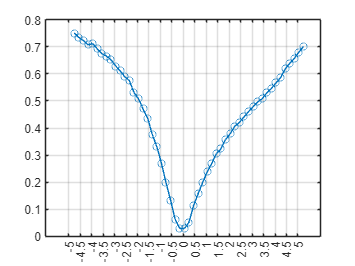


data_xy1 = horzcat(ppm_x1', data1');
%plot(ppm_x,data)
plot(data_xy1(:, 1), data_xy1(:, 2), 'o-')
xticks(-5:0.5:5)
grid on

x = ppm_x1

x =    -4.7573   -4.5573   -4.3573   -4.1573   -3.9573   -3.7573   -3.5573   -3.3573   -3.1573   -2.9573   -2.7573   -2.5573   -2.3573   -2.1573   -1.9573   -1.7573   -1.5573   -1.3573   -1.1573   -0.9573   -0.7573   -0.5573   -0.3573   -0.1573    0.0427    0.2427    0.4427    0.6427    0.8427    1.0427    1.2427    1.4427    1.6427    1.8427    2.0427    2.2427    2.4427    2.6427    2.8427    3.0427    3.2427    3.4427    3.6427    3.8427    4.0427    4.2427    4.4427    4.6427    4.8427    5.0427


y = data1;

[min_val, min_idx] = min(y);

left_part = y(1:min_idx);      % Part of the vector up to the minimum value
right_part = y(min_idx+1:end);

mirrored_left = fliplr(left_part); 
y_mirror1_og = [left_part, mirrored_left];

y_mirror1 = -y_mirror1_og+max(y_mirror1_og);

mirrored_right = fliplr(right_part)

mirrored_right =     0.7009    0.6806    0.6576    0.6387    0.6184    0.5859    0.5670    0.5467    0.5304    0.5088    0.4966    0.4790    0.4601    0.4411    0.4208    0.4060    0.3789    0.3572    0.3234    0.3058    0.2693    0.2382    0.1989    0.1570    0.1123    0.0514


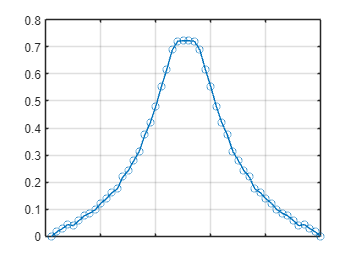

y_mirror2 = [mirrored_right,right_part];

y_mirror2 = -y_mirror2+max(y_mirror2);

plot(y_mirror1,'o-')
grid on
set(gca,'XTickLabel', [])

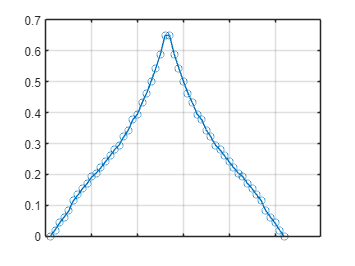


plot(y_mirror2,'o-')
grid on
set(gca,'XTickLabel', [])

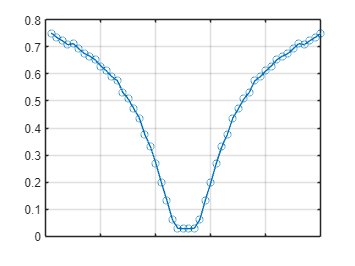


plot(y_mirror1_og,'o-')
grid on
set(gca,'XTickLabel', [])

%GAUSSIAN
x0_g = [1,0,1];
x_mirror1 = linspace(-5,5,length(y_mirror1))

x_mirror1 =    -5.0000   -4.7959   -4.5918   -4.3878   -4.1837   -3.9796   -3.7755   -3.5714   -3.3673   -3.1633   -2.9592   -2.7551   -2.5510   -2.3469   -2.1429   -1.9388   -1.7347   -1.5306   -1.3265   -1.1224   -0.9184   -0.7143   -0.5102   -0.3061   -0.1020    0.1020    0.3061    0.5102    0.7143    0.9184    1.1224    1.3265    1.5306    1.7347    1.9388    2.1429    2.3469    2.5510    2.7551    2.9592    3.1633    3.3673    3.5714    3.7755    3.9796    4.1837    4.3878    4.5918    4.7959    5.0000


params_opt_g_mirror1 = lsqcurvefit(@gaussian,x0_g,x_mirror1,y_mirror1);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



g_mirror1 = @(x) params_opt_g_mirror1(1)*exp(-((x-params_opt_g_mirror1(2))/params_opt_g_mirror1(3)).^2);
[testi,SSE_g_mirror1,rsg_g_mirror1] = gaussian_rsq(params_opt_g_mirror1,x_mirror1,y_mirror1);

rsq = 0.9816


x_mirror2 = linspace(-5,5,length(y_mirror2));
params_opt_g_mirror2 = lsqcurvefit(@gaussian,x0_g,x_mirror2,y_mirror2);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



g_mirror2 = @(x) params_opt_g_mirror2(1)*exp(-((x-params_opt_g_mirror2(2))/params_opt_g_mirror2(3)).^2);
[testi,SSE_g_mirror2,rsg_g_mirror2] = gaussian_rsq(params_opt_g_mirror2,x_mirror2,y_mirror2);

rsq = 0.9558



G1 =1

G1 = 1

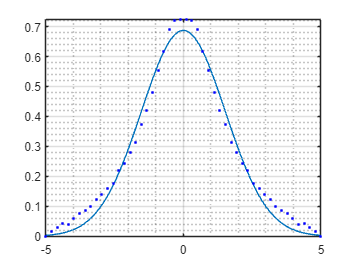

figure; fplot(g_mirror1)
hold on;plot(x_mirror1,y_mirror1,'b.','LineWidth',2)
grid on;
grid minor;
%set(gca,'XTickLabel', [])
hold off;


G2 =1

G2 = 1

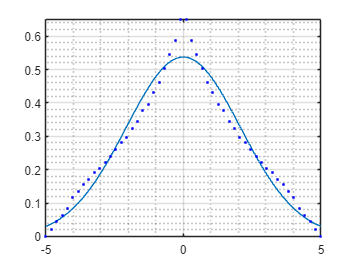

figure; fplot(g_mirror2)
hold on;plot(x_mirror2,y_mirror2,'b.','LineWidth',2)
grid on;
grid minor;
%set(gca,'XTickLabel', [])
hold off;


x0_l = [1,0,1];
params_opt_l_mirror1 = lsqcurvefit(@lorentzian,x0_l, x_mirror1 ,y_mirror1);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



l_mirror1 = @(x) params_opt_l_mirror1(1)./((x-params_opt_l_mirror1(2)).^2 + params_opt_l_mirror1(3).^2);
[testi,SSE_l_mirror1,rsg_l_mirror1] = lorentzian_rsq(params_opt_l_mirror1,x_mirror1,y_mirror1);

rsq = 0.9886


params_opt_l_mirror2 = lsqcurvefit(@lorentzian,x0_l, x_mirror2 ,y_mirror2);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



l_mirror2 = @(x) params_opt_l_mirror2(1)./((x-params_opt_l_mirror2(2)).^2 + params_opt_l_mirror2(3).^2);
[testi,SSE_l_mirror2,rsg_l_mirror2] = lorentzian_rsq(params_opt_l_mirror2,x_mirror1,y_mirror1);

rsq = 0.8417


L1 =1

L1 = 1

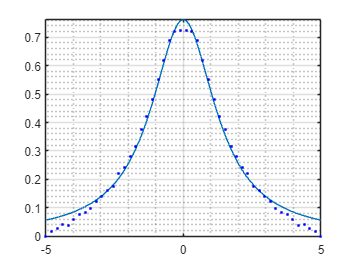

figure; fplot(l_mirror1)
hold on; plot(x_mirror1,y_mirror1,'b.','LineWidth',2)
grid on;
grid minor;
%set(gca,'XTickLabel', [])
hold off;


L2=1

L2 = 1

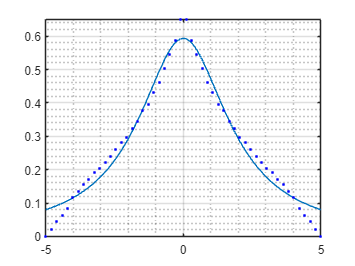

figure; fplot(l_mirror2)
hold on; plot(x_mirror2,y_mirror2,'b.','LineWidth',2)
grid on;
grid minor;
%set(gca,'XTickLabel', [])
hold off;

x0_p = [1,0,1,1, 0, 1,1,1]

x0_p =      1     0     1     1     0     1     1     1


v = pseudovoigt(x0_p, x)

v =     0.0423    0.0459    0.0500    0.0547    0.0600    0.0661    0.0732    0.0815    0.0912    0.1028    0.1167    0.1341    0.1564    0.1864    0.2287    0.2902    0.3804    0.5103    0.6895    0.9217    1.1991    1.4960    1.7669    1.9514    1.9964    1.8872    1.6582    1.3693    1.0763    0.8163    0.6065    0.4493    0.3377    0.2610    0.2087    0.1724    0.1461    0.1262    0.1104    0.0976    0.0869    0.0778    0.0701    0.0634    0.0577    0.0526    0.0482    0.0443    0.0409    0.0378



params_opt_pv_mirror1 = lsqcurvefit(@pseudovoigt,x0_p,x_mirror1,y_mirror1);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



pv_mirror1 = @(x) params_opt_pv_mirror1(7).*(params_opt_pv_mirror1(1).*exp(-((x-params_opt_pv_mirror1(2))/(params_opt_pv_mirror1(3))).^2))+params_opt_pv_mirror1(8).*(params_opt_pv_mirror1(4)./((x-params_opt_pv_mirror1(5)).^2 + params_opt_pv_mirror1(6).^2));
[testi,SSE_pv_mirror1,rsg_pv_mirror1] = pseudovoigt_rsq(params_opt_pv_mirror1,x_mirror1,y_mirror1);

rsq = 0.9978


params_opt_pv_mirror2 = lsqcurvefit(@pseudovoigt,x0_p,x_mirror2,y_mirror2);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



pv_mirror2 = @(x) params_opt_pv_mirror2(7).*(params_opt_pv_mirror2(1).*exp(-((x-params_opt_pv_mirror2(2))/(params_opt_pv_mirror2(3))).^2))+params_opt_pv_mirror2(8).*(params_opt_pv_mirror2(4)./((x-params_opt_pv_mirror2(5)).^2 + params_opt_pv_mirror2(6).^2));
[testi,SSE_pv_mirror2,rsg_pv_mirror2] = pseudovoigt_rsq(params_opt_pv_mirror2,x_mirror2,y_mirror2);

rsq = 0.9702


PV1=1

PV1 = 1

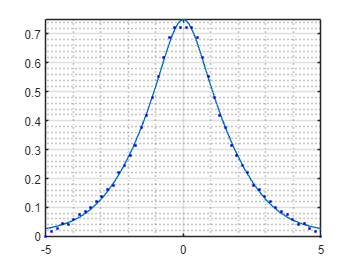

figure; fplot(pv_mirror1)
hold on; plot(x_mirror1,y_mirror1,'b.','LineWidth',2)
grid on;
grid minor;
%set(gca,'XTickLabel', [])
hold off;


PV2=1

PV2 = 1

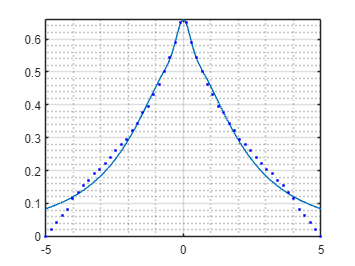

figure; fplot(pv_mirror2)
hold on; plot(x_mirror2,y_mirror2,'b.','LineWidth',2)
grid on;
grid minor;
%set(gca,'XTickLabel', [])
hold off;

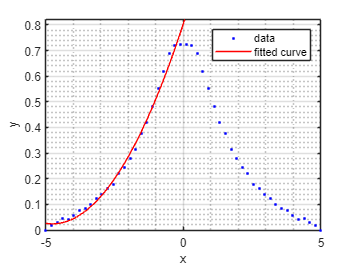

%POLYNOMIAL

[xData, yData] = prepareCurveData( x_mirror1, y_mirror1 );
ft = fittype( 'poly2' );
excludedPoints = xData > 0;
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure;
h = plot( fitresult, xData, yData);
grid on
grid minor;
%set(gca,'XTickLabel', [])

xlim([-5 5])
ylim([0 0.82])

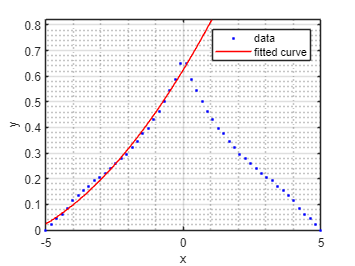


[xData2, yData2] = prepareCurveData( x_mirror2, y_mirror2 );
ft = fittype( 'poly2' );
excludedPoints = xData2 > 0;
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult2, gof] = fit( xData2, yData2, ft, opts );

% Plot fit with data.
figure;
h = plot( fitresult2, xData2, yData2);
grid on
grid minor;
%set(gca,'XTickLabel', [])

xlim([-5 5])
ylim([0 0.82])

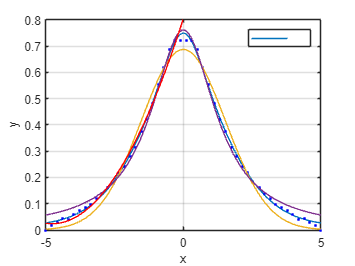

figure; 
fplot(pv_mirror1,"DisplayName","V(x)")
legend(' ');
hold on
plot(x_mirror1,y_mirror1,'b.','LineWidth',2)
fplot(g_mirror1,"DisplayName","G(x)")
legend(' ');
fplot(l_mirror1,"DisplayName","L(x)")
legend(' ');
plot(fitresult)
legend(' ');
grid on
xlim([-5 5])
ylim([0 0.8])

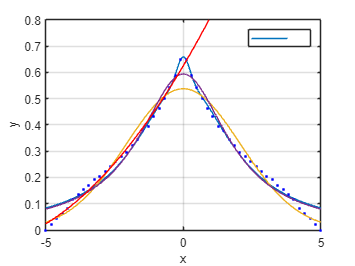




figure; 
fplot(pv_mirror2,"DisplayName","V(x)")
legend(' ');
hold on
plot(x_mirror2,y_mirror2,'b.','LineWidth',2)
fplot(g_mirror2,"DisplayName","G(x)")
legend(' ');
fplot(l_mirror2,"DisplayName","L(x)")
legend(' ');
plot(fitresult2)
legend(' ');
grid on
xlim([-5 5])
ylim([0 0.8])

%integraalien laskeminen
%ref. spektrin integraalit puolittain
%Välit:

int_start = 2.7

int_start = 2.7000

int_end = 4.3

int_end = 4.3000


ppm_x1_integral = ppm_x1;

x_interp = linspace(min(ppm_x1_integral), max(ppm_x1_integral), 100000);  % Define a finer x-grid (e.g., 100 points)
y_interp = interp1(ppm_x1_integral, data1, x_interp, 'linear');  % Linear interpolation

x_start_apt = int_start;  % Example: starting point
x_end_apt = int_end;    % Example: ending point

% Find the indices within the desired range
indices_apt = find(x_interp >= x_start_apt & x_interp <= x_end_apt);

% Perform numerical integration over the desired x-range
integral_ref_apt = trapz(x_interp(indices_apt), y_interp(indices_apt))

integral_ref_apt = 0.8288


x_start_noe = -int_end;  % Example: starting point
x_end_noe = -int_start; 

indices_noe = find(x_interp >= x_start_noe & x_interp <= x_end_noe);

integral_ref_noe = trapz(x_interp(indices_noe), y_interp(indices_noe))

integral_ref_noe = 1.0738

%Fitattujen funktioiden integraalit puolittain
%Gaussian
peak_x_g1 = fminbnd(g_mirror1, -5, 5);  % Minimize negative function
peak_value_g1 = g_mirror1(peak_x_g1);  % Get the peak value at peak_x
peak_g1 = g_mirror1(peak_value_g1);
g_mirror1_int = @(x) -g_mirror1(x)+max(y_mirror1);

peak_x_g2 = fminbnd(g_mirror2, -5, 5);  % Minimize negative function
peak_value_g2 = g_mirror2(peak_x_g2);  % Get the peak value at peak_x
peak_g2 = g_mirror2(peak_value_g2);
g_mirror2_int = @(x) -g_mirror2(x)+ max(y_mirror2);

integral_g_noe=integral(g_mirror1_int,x_start_apt,x_end_apt)

integral_g_noe = 1.0613

integral_g_apt=integral(g_mirror2_int,x_start_apt,x_end_apt)

integral_g_apt = 0.8210



%Lorentzian
peak_x_l1 = fminbnd(l_mirror1, -5, 5);  % Minimize negative function
peak_value_l1 = l_mirror1(peak_x_l1);  % Get the peak value at peak_x
peak_l1 = l_mirror1(peak_value_l1);
l_mirror1_int = @(x) -l_mirror1(x)+max(y_mirror1);

peak_x_l2 = fminbnd(l_mirror2, -5, 5);  % Minimize negative function
peak_value_l2 = l_mirror2(peak_x_l2);  % Get the peak value at peak_x
peak_l2 = l_mirror2(peak_value_l2);
l_mirror2_int = @(x) -l_mirror2(x)+ max(y_mirror2);

integral_l_noe=integral(l_mirror1_int,x_start_apt,x_end_apt)

integral_l_noe = 0.9773

integral_l_apt=integral(l_mirror2_int,x_start_apt,x_end_apt)

integral_l_apt = 0.8040


%Pseudo-Voigt
peak_x_pv1 = fminbnd(pv_mirror1, -5, 5);  % Minimize negative function
peak_value_pv1 = pv_mirror1(peak_x_pv1);  % Get the peak value at peak_x
peak_pv1 = pv_mirror1(peak_value_pv1);
pv_mirror1_int = @(x) -pv_mirror1(x)+max(y_mirror1);

peak_x_pv2 = fminbnd(pv_mirror2, -5, 5);  % Minimize negative function
peak_value_pv2 = pv_mirror2(peak_x_pv2);  % Get the peak value at peak_x
peak_pv2 = pv_mirror2(peak_value_pv2);
pv_mirror2_int = @(x) -pv_mirror2(x)+ max(y_mirror2);

integral_pv_noe=integral(pv_mirror1_int,x_start_apt,x_end_apt)

integral_pv_noe = 1.0114

integral_pv_apt=integral(pv_mirror2_int,x_start_apt,x_end_apt)

integral_pv_apt = 0.7962


%Polynomial

pol1 = @(x) fitresult.p1*x.^2 + fitresult.p2*x + fitresult.p3;
pol1_int = @(x) -pol1(x) + max(y_mirror1);

pol2 = @(x) fitresult2.p1*x.^2 + fitresult2.p2*x + fitresult2.p3;
pol2_int = @(x) -pol2(x) + max(y_mirror2);

integral_pol_noe = integral(pol1_int,x_start_noe,x_end_noe)

integral_pol_noe = 1.0177

integral_pol_apt = integral(pol2_int,x_start_noe,x_end_noe)

integral_pol_apt = 0.8029

%Lasketaan integraalien erotukset
REF_diff = integral_ref_noe - integral_ref_apt

REF_diff = 0.2450


G_diff = integral_g_noe - integral_g_apt

G_diff = 0.2403

L_diff = integral_l_noe - integral_l_apt

L_diff = 0.1732

PV_diff = integral_pv_noe - integral_pv_apt

PV_diff = 0.2153

POL_diff = integral_pol_noe - integral_pol_apt

POL_diff = 0.2148


Excel = [integral_ref_noe;integral_ref_apt;
    integral_g_noe;integral_g_apt;
    integral_l_noe;integral_l_apt;
    integral_pv_noe;integral_pv_apt;
    integral_pol_noe;integral_pol_apt;
    G_diff;L_diff;PV_diff;POL_diff];

filename ="tiedostonimi"

filename = "C:\Users\kalle\OneDrive - Oulun yliopisto\A_GRADU\INT_Results.xlsx"


writematrix(Excel,filename,'Sheet',1,'Range','C28')